# Workflow DES + Agua

**1. Importar los datos de viscosidad**

Visc_Rel=readtable("TFM\DATASET_TFM_DES_H2O.xlsx","Sheet","Visc_Reline","VariableNamingRule","preserve")

Visc_Rel = 544×11 table
         DES             Set Type        Condition_Method       Mixture       Mass_percent_Water    Mass_percent_DES    Temperature(K)    Viscosity(Pa.s)    Viscosity(cP)        Reference         DES mole fraction
    _____________    ________________    ________________    _____________    __________________    ________________    ______________    _______________    _____________    __________________    _________________

    {'ChCl-Urea'}    {'Computed'    }      {'Mean'    }      {'DES+Water'}            0                    1                303.15              0.511              511       

Masa_H2O_Rel=Visc_Rel.Mass_percent_Water*100;
Temp_Rel=Visc_Rel.("Temperature(K)");
Mu_Rel=Visc_Rel.("Viscosity(cP)");
data=[Masa_H2O_Rel,Temp_Rel,Mu_Rel];

**2. Eliminación de outliers con función rmoultiers**

length(data)

ans = 544

data_def = rmoutliers(data); length(data_def)

ans = 378

data_median = rmoutliers(data,'median');length(data_median)

ans = 378

data_mean = rmoutliers(data,'mean');length(data_mean)

ans = 532

data_quart = rmoutliers(data,'quartiles');length(data_quart)

ans = 424

data_grubbs = rmoutliers(data,'grubbs');length(data_grubbs)

ans = 447

data_gesd = rmoutliers(data,'gesd');length(data_gesd)

ans = 483

Gráfica de datos de viscosidad con y sin outliers

Masa_H2O_Rel=Visc_Rel.Mass_percent_Water*100;
Temp_Rel=Visc_Rel.("Temperature(K)");
Mu_Rel=Visc_Rel.("Viscosity(cP)");
figure, plot3(Masa_H2O_Rel,Temp_Rel,Mu_Rel,'ob'); hold on
title('Viscosidad Reline + Agua - Datos procesados'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Visc. \mu [cP]'),
view([40 20])

Gráfica de datos sin outliers mean

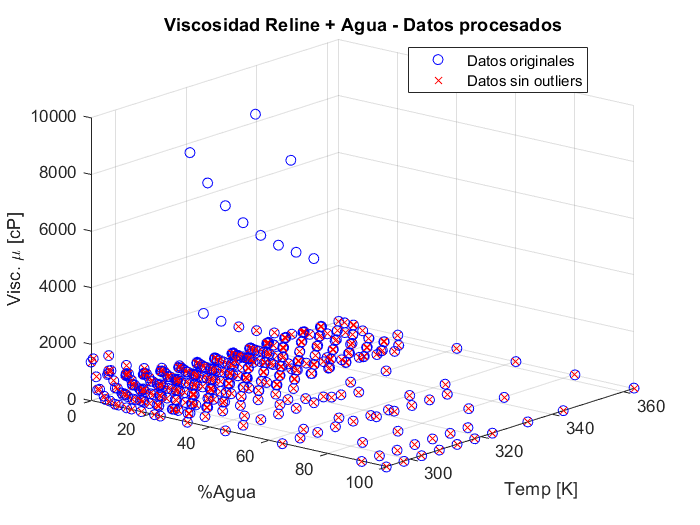

data_mean = rmoutliers(data,'mean');
plot3(data_mean(:,1),data_mean(:,2),data_mean(:,3),'xr')
legend('Datos originales', 'Datos sin outliers',"Location","best")
hold off

**3. División Conjuntos de Datos Entrenamiento y Prueba**

Masa_H2O_Rel=Visc_Rel.Mass_percent_Water*100;
Temp_Rel=Visc_Rel.("Temperature(K)");
Mu_Rel=Visc_Rel.("Viscosity(cP)");
data=[Masa_H2O_Rel,Temp_Rel,Mu_Rel];
data1=rmoutliers(data,'mean');
min(data1(:,3))

ans = 0.2900

max(data1(:,3))

ans = 3107

n=length(data1);
particion=cvpartition(n,'HoldOut',0.2) % Se separa un 20% de datos para prueba

particion = Hold-out cross validation partition
   NumObservations: 532
       NumTestSets: 1
         TrainSize: 426
          TestSize: 106

Datos de entrenamiento

idx_train=training(particion);
train_data_visc1=data1(idx_train,:)

train_data_visc1 = 	1.0e+03 *

         0    0.3031    0.5110
         0    0.3131    0.2430
         0    0.3332    0.0620
         0    0.3431    0.0370
         0    0.3631    0.0200
         0    0.3131    0.2570
         0    0.3332    0.0630
         0    0.3431    0.0390
         0    0.3031    0.4860
         0    0.3131    0.2290



Masa_H2O_Rel_train=train_data_visc1(:,1);
Temp_Rel_train=train_data_visc1(:,2);
Mu_Rel_train=train_data_visc1(:,3);

Datos de prueba

idx_test=test(particion);
test_data_visc1=data1(idx_test,:)

test_data_visc1 = 	1.0e+03 *

         0    0.3031    0.5360
         0    0.3631    0.0210
         0    0.3332    0.0610
         0    0.3031    0.5273
         0    0.3332    0.0687
    0.0020    0.3031    0.2260
    0.0020    0.3332    0.0410
    0.0020    0.3031    0.2167
    0.0050    0.3031    0.0900
    0.0050    0.3031    0.0880



Masa_H2O_Rel_test=test_data_visc1(:,1);
Temp_Rel_test=test_data_visc1(:,2);
Mu_Rel_test=test_data_visc1(:,3);



**4. Regresión fitlm**

predictores_train=[Masa_H2O_Rel_train Temp_Rel_train];
regre_visc_rel = fitlm(predictores_train,Mu_Rel_train)

regre_visc_rel = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      1600.6     293.87     5.4467    8.7318e-08
    x1             0.059784    0.63037    0.09484       0.92449
    x2              -4.5206    0.90344    -5.0038    8.2684e-07


Number of observations: 425, Error degrees of freedom: 422
Root Mean Squared Error: 366
R-squared: 0.0561,  Adjusted R-Squared: 0.0516
F-statistic vs. constant model: 12.5, p-value = 5.14e-06

Ecuacion

coef1=table2array(regre_visc_rel.Coefficients(1,1));
coef2=table2array(regre_visc_rel.Coefficients(2,1));
coef3=table2array(regre_visc_rel.Coefficients(3,1));

fprintf('Ecuación')

Ecuación

fprintf('Viscosidad= %0.4f+(%0.4f)*%%Agua+(%0.4f)*Temperatura',coef1, coef2, coef3)

Viscosidad= 1600.6436+(0.0598)*%Agua+(-4.5206)*Temperatura

fprintf('Rango de porcentaje: %0.2f %% - %0.2f %%', min(Masa_H2O_Rel_train),max(Masa_H2O_Rel_train))

Rango de porcentaje: 0.00 % - 100.00 %

fprintf('Rango de temperatura: %0.2f K - %0.2f K', min(Temp_Rel_train),max(Temp_Rel_train))

Rango de temperatura: 293.15 K - 363.15 K

**4.1 Regresión toolbox**

predictores_train=[Masa_H2O_Rel_train Temp_Rel_train];
data_regresion_visc=[predictores_train Mu_Rel_train];
data_regresion_visc=array2table(data_regresion_visc,"VariableNames", ...
    {'Mass_percent_Water','Temperature(K)','Viscosity(cP)'})

data_regresion_visc = 426×3 table
    Mass_percent_Water    Temperature(K)    Viscosity(cP)
    __________________    ______________    _____________

            0                 303.15              511    
            0                 313.15              243    
            0                 333.15               62    
            0                 343.15               37    
            0                 363.15               20    
            0                 313.15              257    
            0                 333.15               63    
            0                 343.15               39    
            0                 303.15              486    
            0                 313.15              229    
            0                 343.15               35    
            0                 363.15               19    
            0                 313.15           238.


predictores_test=[Masa_H2O_Rel_test Temp_Rel_test];
data_test_visc=[predictores_test Mu_Rel_test];
data_test_visc=array2table(data_test_visc,"VariableNames", ...
    {'Mass_percent_Water','Temperature(K)','Viscosity(cP)'})

data_test_visc = 106×3 table
    Mass_percent_Water    Temperature(K)    Viscosity(cP)
    __________________    ______________    _____________

             0                303.15              536    
             0                363.15               21    
             0                333.15               61    
             0                303.15           527.28    
             0                333.15            68.65    
             2                303.15              226    
             2                333.15               41    
             2                303.15           216.72    
             5                303.15               90    
             5                303.15            88.04    
            20                343.15             3.43    
            40                363.15              1.1    
            40                313.15              2.6   

[regre_visc_rel, validationRMSE] = FineTree_Visc_Reline(data_regresion_visc)

regre_visc_rel = struct with fields:
           predictFcn: @(x)treePredictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'Mass_percent_Water'  'Temperature(K)'}
       RegressionTree: [1×1 RegressionTree]
                About: 'This struct is a trained model exported from Regression Learner R2021a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 293.7694

regre_visc_rel.HowToPredict

ans =     'To make predictions on a new table, T, use: 
       yfit = c.predictFcn(T) 
     replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. 
      
     The table, T, must contain the variables returned by: 
       c.RequiredVariables 
     Variable formats (e.g. matrix/vector, datatype) must match the original training data. 
     Additional variables are ignored. 
      
     For more information, see How to predict using an exported model.'
